# **ELEC-H-314 : Instrumentation**

# *Laboratoire 2, partie 2: Filtres numériques*

## Information préliminaire

Le laboratoire se déroule au sein d'un "LiveScript" MATLAB. Ce dernier contient du code qu'il faut compléter afin de répondre aux différents exercices.

Si vous n'êtes pas familier avec l'éditeur MATLAB et les commandes usuelles, il est conseillé de réaliser le tutoriel [MATLAB Onramp](https://fr.mathworks.com/learn/tutorials/matlab-onramp.html) avant le laboratoire.

**Il ne sera PAS demandé de coder ou de lire du code MATLAB à l'examen. **

## Toolboxes requises

Cette séance nécessite les toolboxes suivantes:

- [Signal Processing Toolbox](https://nl.mathworks.com/products/signal.html)

- [Control System Toolbox](https://nl.mathworks.com/products/control.html)

## Objectifs du laboratoire

- Dimensionner un filtre numérique en utilisant la transformation bilinéaire à partir d'un prototype de filtre analogique.

- Réaliser le filtre sous Matlab.

- Observer les problèmes de quantification.

## Rappels

Nous avons vu dans la dernière séance comment dimensionner un prototype de filtre analogique afin de respecter un gabarit. Il arrive également que l'on doive réaliser un filtre numérique (au sein du code d'un microcontrôleur par exemple). Il existe plusieurs méthodes afin de dimensionner un filtre numérique. La méthode la plus courante est de dimensionner un filtre analogique et de le transposer en un filtre numérique. De cette manière, on peut réutiliser tous les résultats connus pour les filtres analogiques, par exemple les solutions de type Butterworth, Chebyshev, elliptique, ...

Deux méthodes permettent de transformer un filtre analogique en filtre numérique :

- La transformation bilinéaire (bilinear transform)

- L’échantillonnage de la réponse impulsionnelle (impulse invariance)

Bien que les deux méthodes soient utilisables et ont leurs avantages et inconvénients, nous verrons ici la transformation bilinéaire qui est la plus couramment utilisée car elle conserve la stabilité des filtres, ne provoque pas de repliement spectral supplémentaire, et qu'elle peut s'appliquer à n'importe quel type de filtre.

L'annexe "*Transformation bilinéaire*" décrit la méthode.

clearvars %clear the workspace
clc
cd(fileparts(matlab.desktop.editor.getActiveFilename)); %Changes location to script directory

# Exercice 1: Transformation bilinéaire

En utilisant la transformation bilinéaire, déterminez un filtre numérique (en $z$) respectant le gabarit ci-dessous.

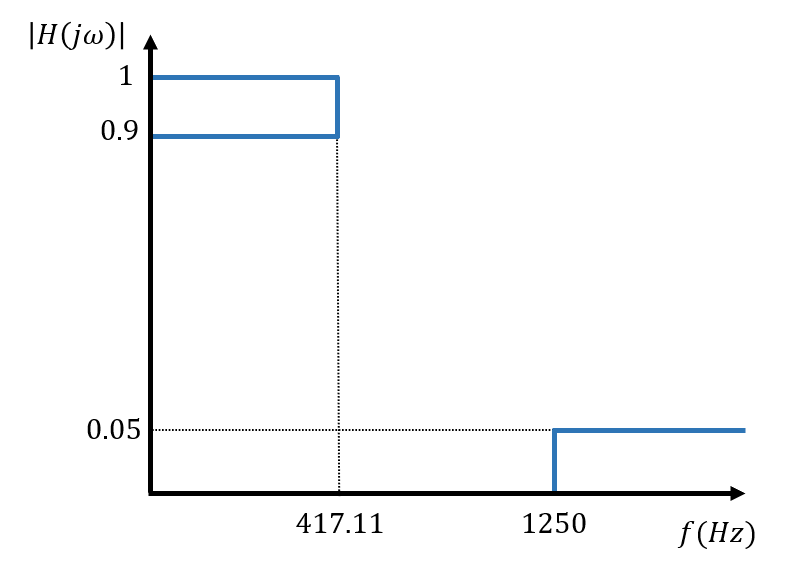

1. Déterminez l'ordre et la pulsation de coupure du** filtre analogique** respectant ce gabarit ainsi que sa fonction de transfert $H\left(p\right)$. La fonction Matlab [buttord](https://fr.mathworks.com/help/signal/ref/buttord.html) réalise l'approximation de Butterworth **en respectant la bande d'arrêt exactement**. Par défaut, cette fonction travaille dans le domaine numérique (fréquences normalisées par rapport à la fréquence de Nyquist). Vérifiez la syntaxe requise pour travailler dans le domaine analogique. La fonction [butter](https://fr.mathworks.com/help/signal/ref/butter.html) permet d'obtenir le numérateur et le dénominateur de la fonction de transfert du filtre analogique.

%% Transformation bilineaire
gainPassant = mag2db(0.9);
gainStop = mag2db(0.05);
 [n,wc] = buttord(417.11*2*pi,1250*2*pi, gainPassant, gainStop ,'s') % buttord returns min order and cut-off w 

n = 4

wc = 3.7151e+03

fc = wc/(2*pi)

fc = 591.2735

%compare the obtained fc with results from the previous lab and explain 

 [numA,denA] = butter(n, wc, 's');%find the TF       
LPa = tf(numA,denA)

LPa =
 
                        1.905e14
  ----------------------------------------------------
  s^4 + 9708 s^3 + 4.712e07 s^2 + 1.34e11 s + 1.905e14
 
Continuous-time transfer function.
Model Properties


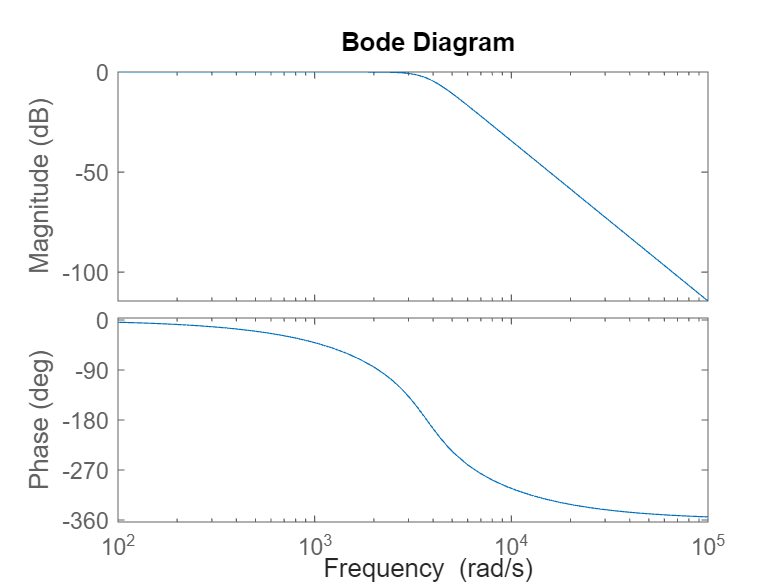


figure('Name', 'Bode plots')
bode(LPa)

2. Sans la résoudre ou la simplifier, exprimez la fonction de transfert du filtre **numérique** équivalent (sur papier).

3. A l'aide de l'approximation bilinéaire ([bilinear](https://fr.mathworks.com/help/signal/ref/bilinear.html)), déterminez la fonction $H\left(z\right)$ du filtre numérique équivalent, sachant que le système numérique possède une fréquence d'échantillonage de 10kHz.

 Fs = 10000; %Sampling frequency
 [NumD,DenD]=bilinear(numA, denA, Fs);

LPd=tf(NumD,DenD,1/Fs)

LPd =
 
  0.0007344 z^4 + 0.002938 z^3 + 0.004406 z^2 + 0.002938 z + 0.0007344
  --------------------------------------------------------------------
             z^4 - 3.043 z^3 + 3.56 z^2 - 1.886 z + 0.3805
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


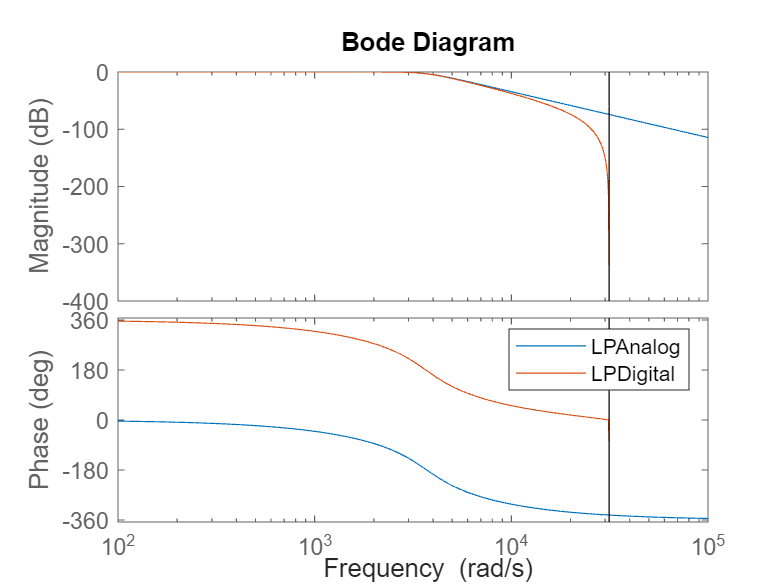

figure('Name', 'Bode plots')
bode(LPa)
hold on
bode(LPd)
legend('LPAnalog','LPDigital')

4. La fonction [butter](https://fr.mathworks.com/help/signal/ref/butter.html) permet également d'obtenir directement le numérateur et le dénominateur de la fonction de transfert numérique. Il est également possible d'utiliser la fonction [c2d](https://fr.mathworks.com/help/control/ref/lti.c2d.html) (continuous to digital), en spécifiant la méthode "Tustin" (autre nom de la transformation bilinéaire), pour transformer une fonction de transfert en p en une fonction de transfert en z. Comparez les fonctions de transfert et les courbes de Bode obtenues.

[NumDbis,DenDbis] = butter(n,(wc/(2*pi))/(Fs/2),'low'); %this method works in normalized frequency!
LPdbis = tf(NumDbis,DenDbis,1/Fs)

LPdbis =
 
  0.000765 z^4 + 0.00306 z^3 + 0.00459 z^2 + 0.00306 z + 0.000765
  ---------------------------------------------------------------
          z^4 - 3.032 z^3 + 3.537 z^2 - 1.869 z + 0.3763
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


LPdter = c2d(LPa,1/Fs,'tustin') %continuous to digital transformation, tustin = bilinear method (synonym)

LPdter =
 
  0.0007344 z^4 + 0.002938 z^3 + 0.004406 z^2 + 0.002938 z + 0.0007344
  --------------------------------------------------------------------
             z^4 - 3.043 z^3 + 3.56 z^2 - 1.886 z + 0.3805
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


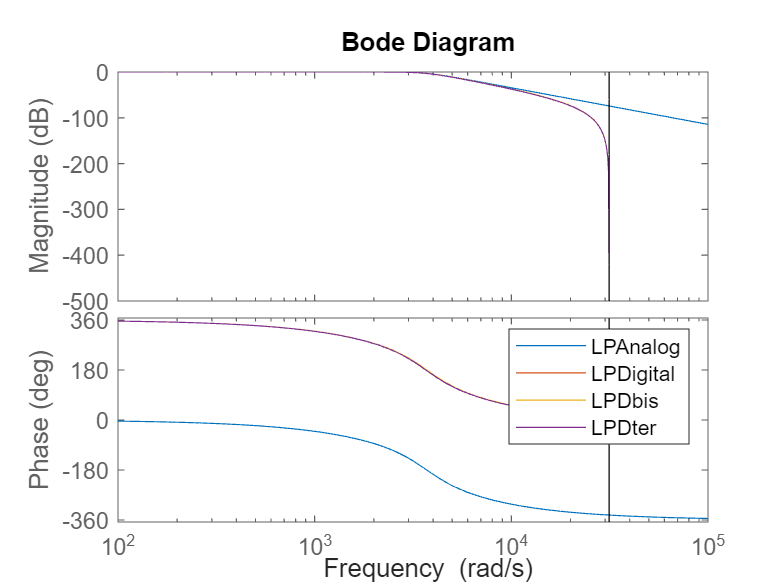


figure('Name', 'Bode plots')
bode(LPa)
hold on
bode(LPd)
bode(LPdbis)
bode(LPdter) 
legend('LPAnalog','LPDigital', 'LPDbis', 'LPDter')

5. Comparez les réponses en fréquences des filtres numériques et du filtre analogique et concluez sur la distorsion due à l'approximation bilinéaire.

6. Proposez une solution pour que le filtre numérique ait la même atténuation que le filtre analogique pour$f=3\ldotp 2\;\textrm{kHz}$. Implémentez cette solution via les options ([c2dOptions](https://fr.mathworks.com/help/ident/ref/c2doptions.html)) de la fonction [c2d](https://fr.mathworks.com/help/control/ref/lti.c2d.html).

 options = c2dOptions('Method', 'tustin', 'PrewarpFrequency', 3200*2*pi); %sets specific options for c2d
LPDquad = c2d(LPa,1/Fs,options) %using the option set above to implement the solution

LPDquad =
 
  0.003387 z^4 + 0.01355 z^3 + 0.02032 z^2 + 0.01355 z + 0.003387
  ---------------------------------------------------------------
          z^4 - 2.528 z^3 + 2.575 z^2 - 1.215 z + 0.2221
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


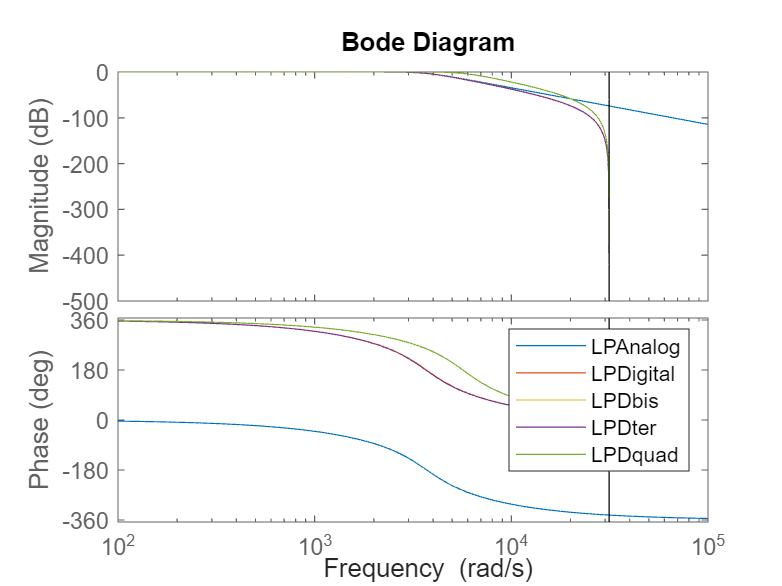

bode(LPDquad)
legend('LPAnalog','LPDigital', 'LPDbis', 'LPDter', 'LPDquad')